%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%% Image Display %%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear all;
close all;
clc;

%--------------------------------------------------------------------------

## 1.2 An image as a "byte stream"

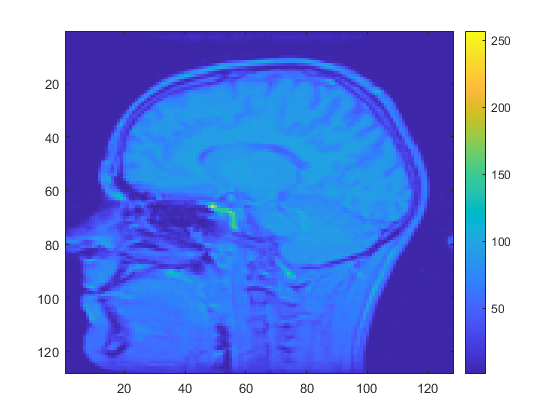


%1.2.1 load raw data, head file

fid=fopen('head.128','r');
[x,npels]=fread(fid,[128,128],'uchar'); % Reads data values  
                                        % into matrix x with 128 rows,
                                        % and 128 columns
x=x' ;
fclose(fid); %close file handle
figure(1);
image(x);
colorbar;

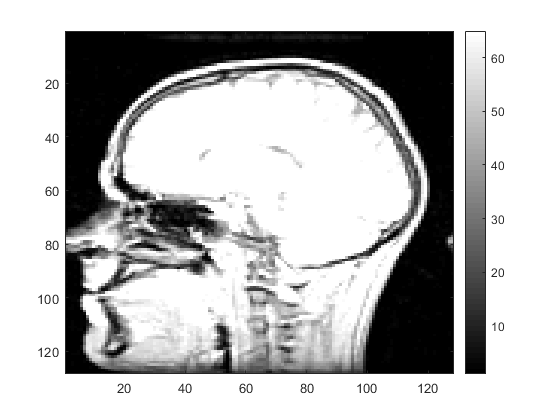

figure(2)
image(x);
colormap(gray(64));colorbar;

## Custom colormap

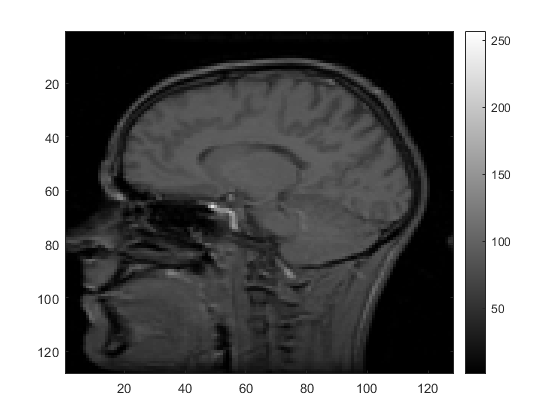

NSteps = 256;
delta = 1/(NSteps-1);
ramp = [0:delta:1]';
custom_greymap(:,1) = ramp;
custom_greymap(:,2) = ramp;
custom_greymap(:,3) = ramp;

figure(3)
image(x);
colormap(custom_greymap);colorbar;

## 1.5 Custom colormap (coloured)

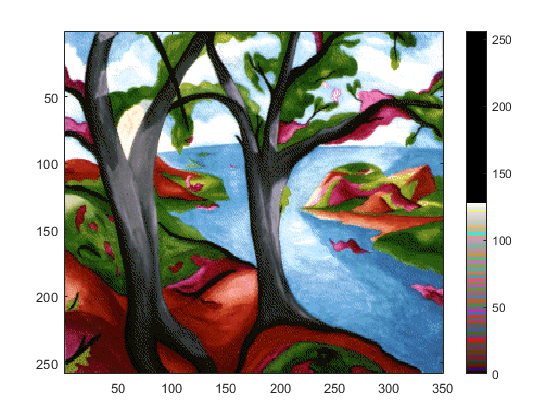

% clear all;
[X,map] =imread('trees.tif');
figure(4)
image(X);
colormap(map);colorbar;

## 1.6 True color RGB images

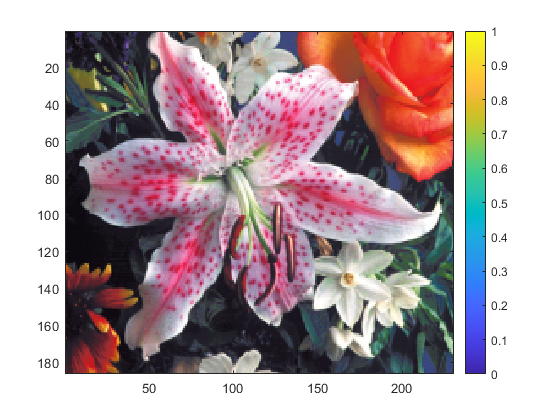

[X,map] =imread('lily.tif');
figure(5);
image(X); colorbar;

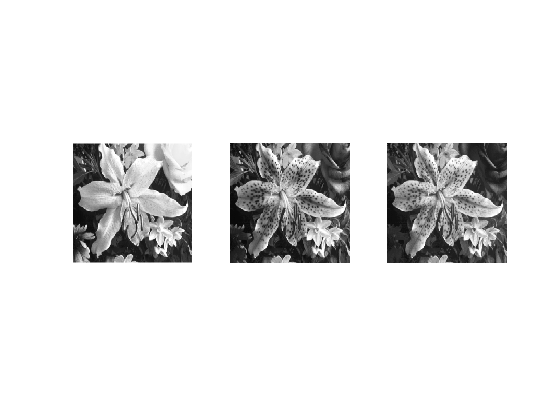

figure(6)
% To display each of the individual channels, we can use
R=X(:,:,1);
G=X(:,:,2);
B=X(:,:,3);

colour_ramp=[0:1/255:1]';
redmap=[colour_ramp,zeros(256,1),zeros(256,1)];
greenmap=[zeros(256,1),colour_ramp,zeros(256,1)];
bluemap=[zeros(256,1),zeros(256,1),colour_ramp];

subplot(1,3,1);image(R);axis square; axis off
subplot(1,3,2);image(G);axis square; axis off
subplot(1,3,3);image(B);axis square; axis off
colormap(gray(256));

### Trichromatic values (normalised RGB)

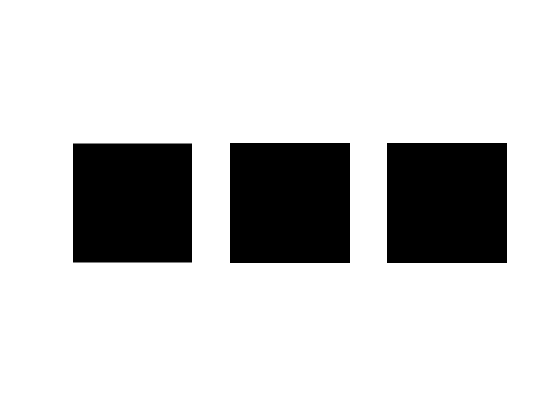

%trichromatic values
D = double(R) + double(G) + double(B); 
x = double(R)./D;
y = double(G)./D;
z = double(B)./D;

figure(7);
subplot(1,3,1);image(x);axis square; axis off
subplot(1,3,2);image(y);axis square; axis off
subplot(1,3,3);image(z);axis square; axis off
colormap(gray(256));

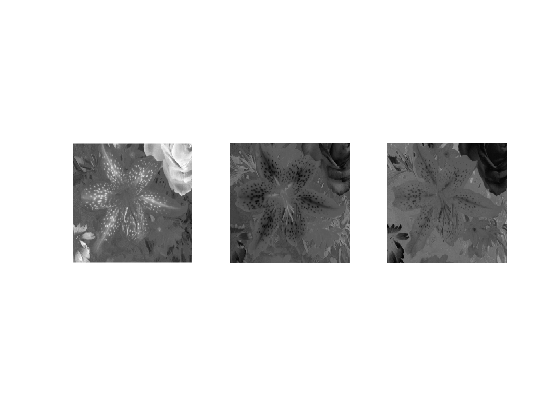


%normailse intensity values

max_intensity=max([x(:);y(:);z(:)]);
min_intensity=min([x(:);y(:);z(:)]);

n_x=1+round(255*(x-min_intensity)/(max_intensity-min_intensity));
n_y=1+round(255*(y-min_intensity)/(max_intensity-min_intensity));
n_z=1+round(255*(z-min_intensity)/(max_intensity-min_intensity));

figure(8);
subplot(1,3,1);image(n_x);axis square; axis off
subplot(1,3,2);image(n_y);axis square; axis off
subplot(1,3,3);image(n_z);axis square; axis off
colormap(gray(256));

## 1.7 Dicom 3.0

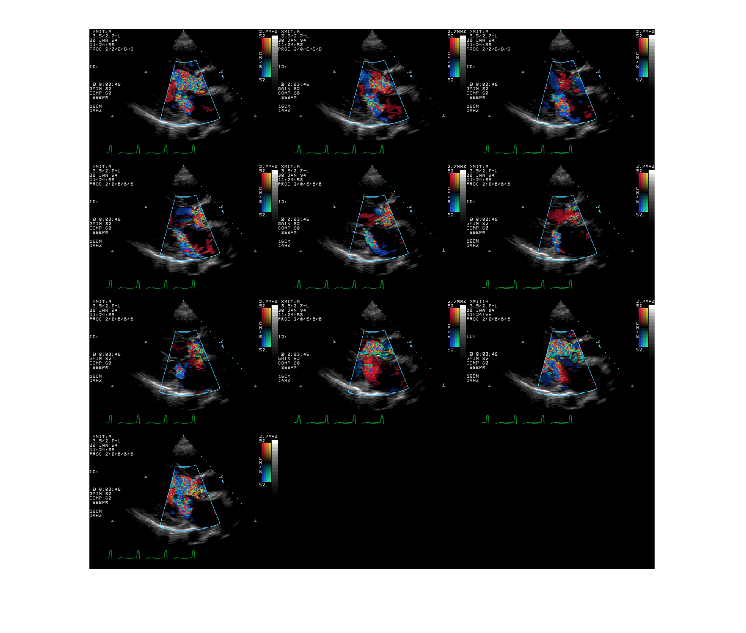

info = dicominfo('US-PAL-8-10x-echo.dcm'); 
[X, map] = dicomread('US-PAL-8-10x-echo.dcm'); %X contains10 images
figure(9)
montage(X, map); %montage: display multyimage data in array config



%display as a moving sequence
M=immovie(X,map);
% movie(M,20,10); 

## 1.8 "Stretch" (binary-moving blood)

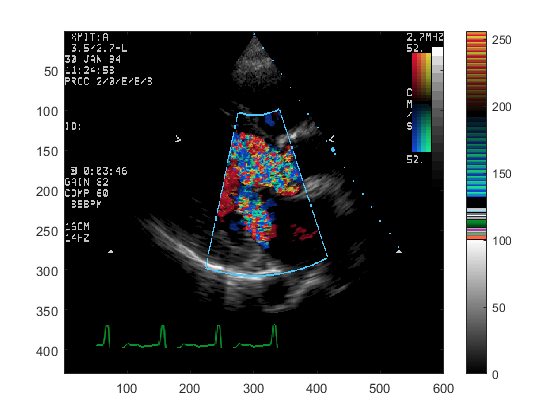

figure(11);
image(X(:,:,:,1)); 
colormap(map);colorbar;

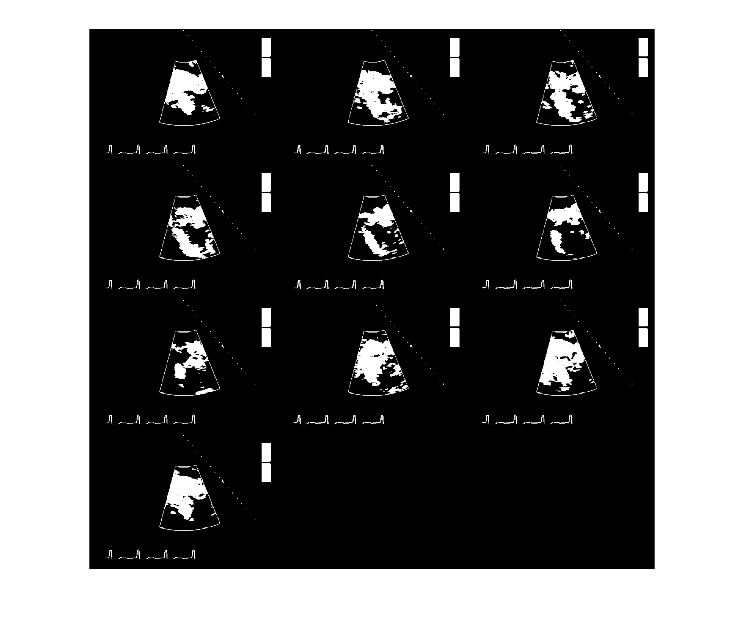


binary_map=(map(:,1)-map(:,2)~=0 | map(:,3)-map(:,2)~=0);
binary_map=double([binary_map,binary_map,binary_map]);
figure(12);
montage(X,binary_map);


M=immovie(X,binary_map);
% movie(M,20,10); 